# Steady State Response

## Comparing the SWA vs Lateral Acceleration response for each vehicle.

Run this line after completing the simulation with the appropriate parameters for the formula vehicle to save the output, and then comment out this line once again.

%Formula_Steady_State_20s = out

Run this line after completing the simulation with the appropriate parameters for the road vehicle to save the output, and then comment out this line once again.

%Road_Vehicle_Steady_State_40s = out

Loading pre-saved simulation outputs:

load("Formula_SteadyState_20s.mat")
load("Road_Vehicle_SteadyState_40s.mat")

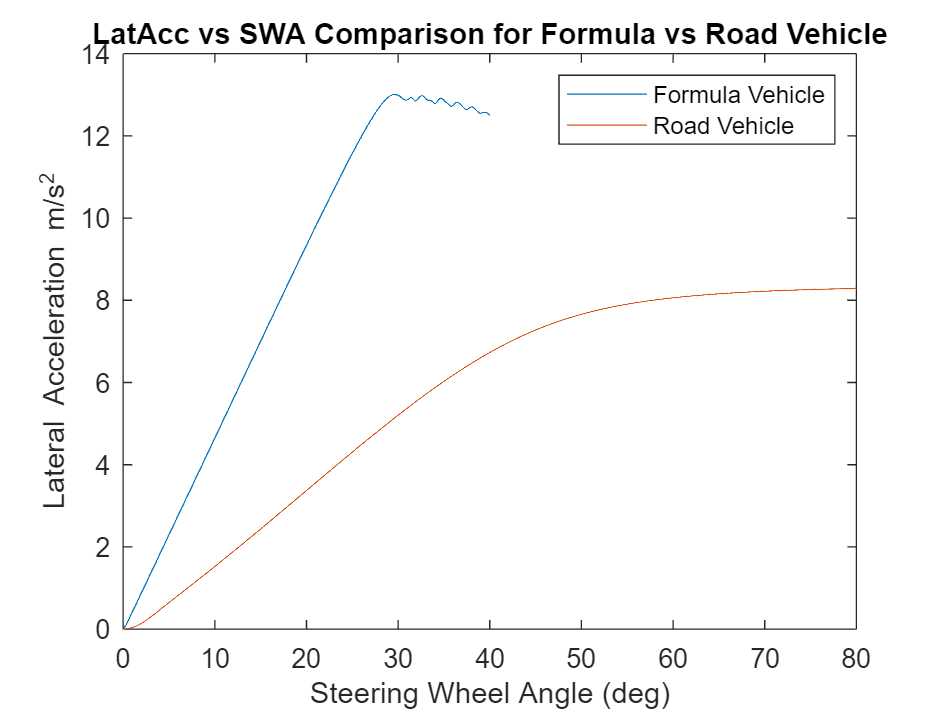

plot(Formula_Steady_State_20s.SWA.Data, Formula_Steady_State_20s.latacc.Data);
hold on
plot(Road_Vehicle_Steady_State_40s.SWA.Data, Road_Vehicle_Steady_State_40s.latacc.Data);
xlabel("Steering Wheel Angle (deg)")
ylabel("Lateral Acceleration m/s^2")
title("LatAcc vs SWA Comparison for Formula vs Road Vehicle")
legend(["Formula Vehicle", "Road Vehicle"])
hold off

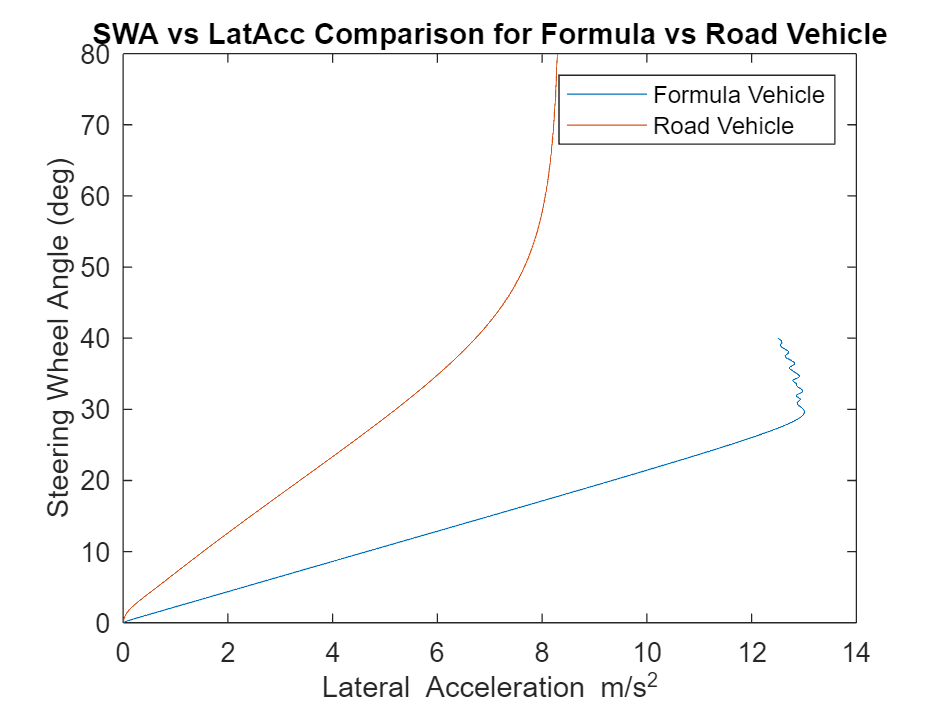


plot(Formula_Steady_State_20s.latacc.Data, Formula_Steady_State_20s.SWA.Data);
hold on
plot(Road_Vehicle_Steady_State_40s.latacc.Data, Road_Vehicle_Steady_State_40s.SWA.Data);
ylabel("Steering Wheel Angle (deg)")
xlabel("Lateral Acceleration m/s^2")
title("SWA vs LatAcc Comparison for Formula vs Road Vehicle")
legend(["Formula Vehicle", "Road Vehicle"])
hold off

Comparing these two vehicles and the change in lateral acceleration due to steering wheel angle input, we can see that clearly the formula vehicle has a higher response to the driver input. In part, this is due to the steering ratio being 10 for the formula vehicle but 20 for the road vehicle, meaning the steering wheel input translates to greater physical turning of the front axle for the formula vehicle, and therefore we expect a greater change in response. This output is also due to the varying vehicle parameters for each vehicle type, given the formula vehicle is lighter, has a longer wheelebase and lower yaw inertia, it is expected to be more responsive to driver steering input than a road vehicle under the steady state constant velocity conditions modelled here.

We can observe from the graph that in the linear region (~2-4 ms^-2 of lateral acceleration) the formula vehicle shows a gradient of ~0.47 ms^-2 of lateral acceleration per degree of steering wheel input angle, while the road vehicle shows a much shallower response of ~0.19 ms^-2 / deg.

Considering the inverse, the road vehicle requires more steering wheel angle input from the driver to maintain a constant radius for a given velocity than the formula vehicle requires.

## Calculating the understeer gradient of each vehicle.

Assuming the LatAcc vs SWA gradient to be 0.5ms^-2 / deg for the FV, therefore SWA vs LatAcc gradient is approximated as 2 deg / ms^-2.

Assuming the LatAcc vs SWA gradient to be 0.2ms^-2 / deg for the RV, therefore SWA vs LatAcc gradient is approcimated as 5 deg / ms^-2.

K_us = [(dSWA/dLatAcc) / SR] - [(L/V^2) .* 180/pi]

Kus_FormulaV = (2 .* (1/10)) - ((3.5 / ((120/3.6)^2)) .* (180/pi))

Kus_FormulaV = 0.0195

Kus_RoadV = (5 .* (1/20)) - ((2.8 / ((120/3.6)^2)) .* (180/pi))

Kus_RoadV = 0.1056

With the Formula Vehicle having an understeer ratio of ~0.0195 and the Road Vehicle having an understeer ratio of ~0.1056, we can see that both vehicles are set up to have more understeer than oversteer. However, the formula vehicle is closer to a neutral setup than the road vehicle, since it has an understeer ratio ~5x less - in line with the epxectation that the road vehicle will need 5 times more steering wheel input to maintain a constant radius for a given velocity in this steady state model. Recall that a neutral vehicle, with understeer gradient 0, will allow the driver to maintain a constant steering wheel angle input and maintain the path radius independent of the vehicle speed.

## Comparing Side Slip vs Lateral Acceleration for each vehicle.

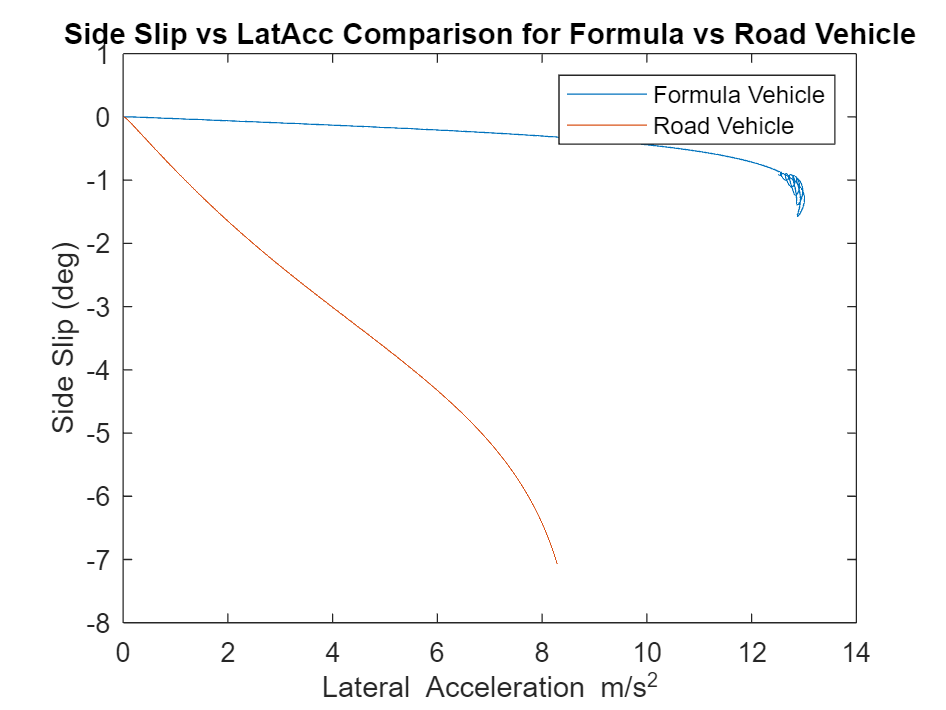

plot(Formula_Steady_State_20s.latacc.Data, Formula_Steady_State_20s.sideslip.Data);
hold on
plot(Road_Vehicle_Steady_State_40s.latacc.Data, Road_Vehicle_Steady_State_40s.sideslip.Data);
ylabel("Side Slip (deg)")
xlabel("Lateral Acceleration m/s^2")
title("Side Slip vs LatAcc Comparison for Formula vs Road Vehicle")
legend(["Formula Vehicle", "Road Vehicle"])
hold off

Comparing the trend of each line, we can clearly see the formula vehicle retains minimal side slip (magnitude) as the lateral acceleration increases, with a gradient of ~-0.1 deg / ms^-2. This means that the side slip increases in magnitude by 0.1 degree for each unit m/s^2 increase of lateral acceleration. In comparison, the road vehicle shows a steep increase in side slip angle magnitude for each unit lateral acceleration, with a gradient of ~-2.3 deg / ms^-2. Recalling that the vehicle sideslip angle is the angle offset between the direction of the wheel and the direction of motion of the vehicle, we expect this angle to be greater in an understeer scenario compared to a balanced or neutral vehicle setup, and so this outpur is as expected, since we already determined that the formula vehicle is extremely close to neutral, whereas the road vehicle has greater understeer ratio.

# Step Steer Response

## Comparing Lateral Acceleration Overshoot

Run this line after completing the simulation with the appropriate parameters for the formula vehicle to save the output, and then comment out this line once again.

%Formula_Step_Steer_10s = out

Run this line after completing the simulation with the appropriate parameters for the road vehicle to save the output, and then comment out this line once again.

%Road_Vehicle_Step_Steer_10s = out

Loading pre-saved simulation outputs:

load("Formula_StepSteer_10s.mat")
load("Road_Vehicle_StepSteer_10s.mat")

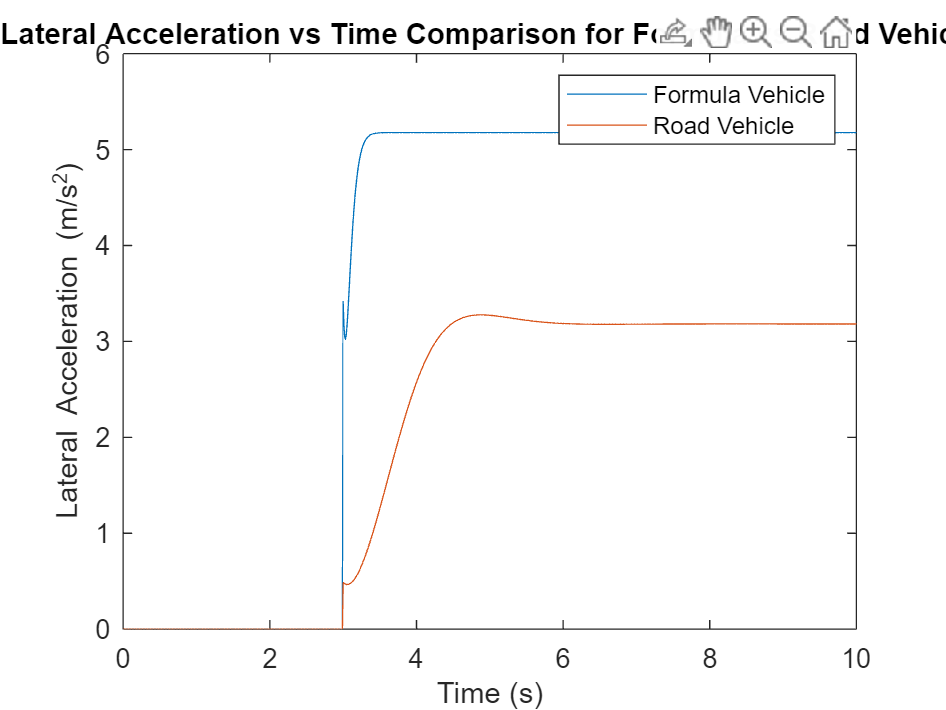

plot(Formula_Step_Steer_10s.latacc.Time, Formula_Step_Steer_10s.latacc.Data);
hold on
plot(Road_Vehicle_Step_Steer_10s.latacc.Time, Road_Vehicle_Step_Steer_10s.latacc.Data);
ylabel("Lateral Acceleration (m/s^2)")
xlabel("Time (s)")
title("Lateral Acceleration vs Time Comparison for Formula vs Road Vehicle (Step Steer)")
legend(["Formula Vehicle", "Road Vehicle"])
hold off

## Calculating the Lateral Acceleration Overshoot for each vehicle

Overshoot (%) = 100 .* [(Maximum Value - Steady State Value) / (Steady State Value)]

LatAcc_Overshoot_FV = 100 .* ((max(Formula_Step_Steer_10s.latacc.Data) - Formula_Step_Steer_10s.latacc.Data(end)) / Formula_Step_Steer_10s.latacc.Data(end))

LatAcc_Overshoot_FV = 5.0004e-04

LatAcc_Overshoot_RV = 100 .* ((max(Road_Vehicle_Step_Steer_10s.latacc.Data) - Road_Vehicle_Step_Steer_10s.latacc.Data(end)) / Road_Vehicle_Step_Steer_10s.latacc.Data(end))

LatAcc_Overshoot_RV = 2.9792

From the graph it is clear to see the road vehicle has a greater overshoot before settling to the steady state lateral acceleration value, which also takes longer than the formula vehicle. After 3s, when the steering input is applied (11 deg for the formula vehicle and 18 deg for the road vehicle) the formula vehicle reaches a localised maximum and minimum before increasing to the global maximum and steady state value. By appearance alone it is clear the formula vehicle has a much more aggresive response, while the road vehicle is smoother in its response to the step steer input, however, still showing localised maximum and minimum immediately after the input at 3s. The formula vehicle exhibits essentially no lateral acceleration overshoot (0.0005%) while the road vehicle overshoots by ~3% (2.9792%). This is expected, sine the performance and repsonsiveness of the formula vehicle should be greater than that of a road vehicle.

## Comparing Yaw Rate Overshoot

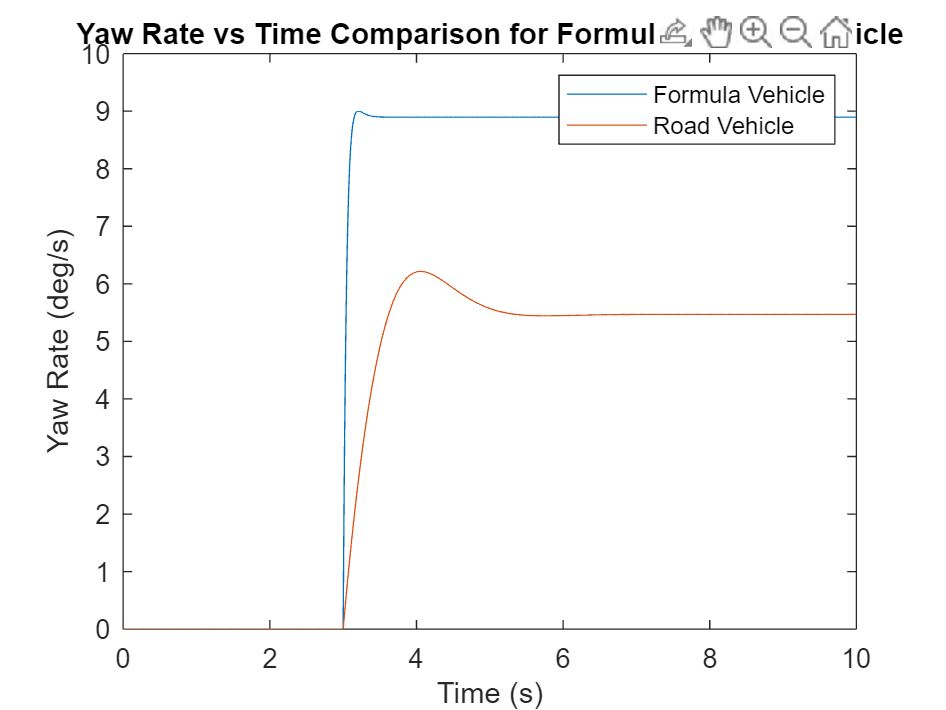

plot(Formula_Step_Steer_10s.yawrate.Time, Formula_Step_Steer_10s.yawrate.Data);
hold on
plot(Road_Vehicle_Step_Steer_10s.yawrate.Time, Road_Vehicle_Step_Steer_10s.yawrate.Data);
ylabel("Yaw Rate (deg/s)")
xlabel("Time (s)")
title("Yaw Rate vs Time Comparison for Formula vs Road Vehicle (Step Steer)")
legend(["Formula Vehicle", "Road Vehicle"])
hold off

## Calculating the Yaw Rate Overshoot for each vehicle

Overshoot (%) = 100 .* [(Maximum Value - Steady State Value) / (Steady State Value)]

YawRate_Overshoot_FV = 100 .* ((max(Formula_Step_Steer_10s.yawrate.Data) - Formula_Step_Steer_10s.yawrate.Data(end)) / Formula_Step_Steer_10s.yawrate.Data(end))

YawRate_Overshoot_FV = 1.1642

YawRate_Overshoot_RV = 100 .* ((max(Road_Vehicle_Step_Steer_10s.yawrate.Data) - Road_Vehicle_Step_Steer_10s.yawrate.Data(end)) / Road_Vehicle_Step_Steer_10s.yawrate.Data(end))

YawRate_Overshoot_RV = 13.6520

From the graph it is clear to see the relative yaw rate overshoot is one again greater for the road vehicle than the formula vehicle. In addition, we can see that the time taken for the overshoot to settle to the steady state yaw rate value is longer for the road vehicle than the formula vehicle. With the formula vehicle yaw rate overshoot only ~1.2% (1.1642%) compared to the road vehicle's ~13.7% (13.6520%) it is clear that the performance of the formula vehicle is greater. This is further reflected by the time taken for the vehicle response to reach its steady state condition being significantly greater for the road vehicle compared to the formula vehicle.

## Comparing Response Time

Steady state yaw rate values assumed as 8.90 for FV and 5.47 for RV (2dp)

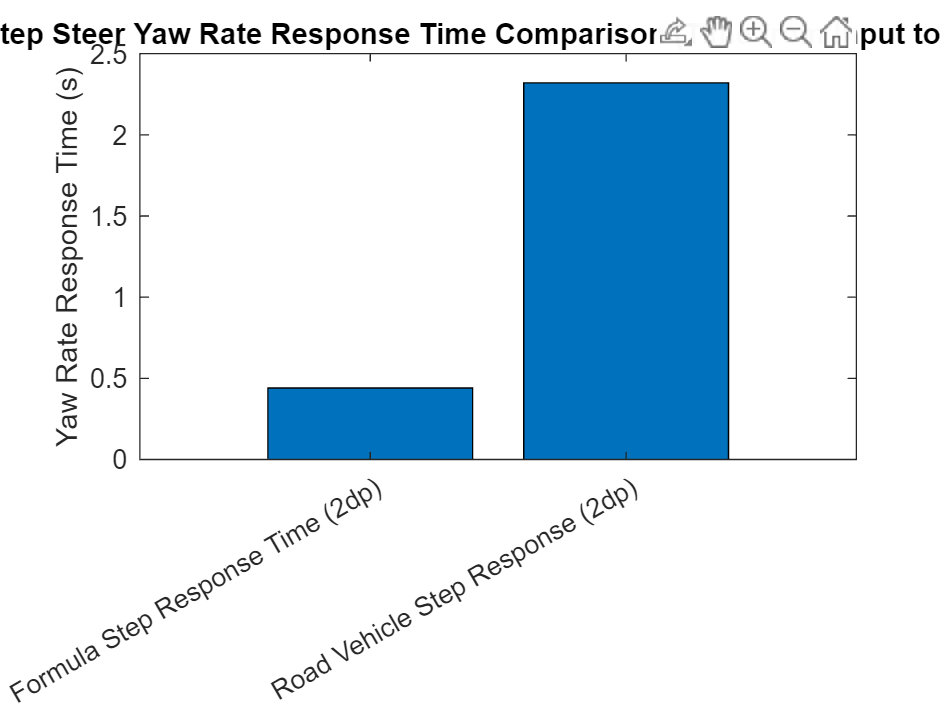

%Indexing into the time data to find the times when the yaw rate is equal to the steady state value.

FV_step_response_time_2dp = Formula_Step_Steer_10s.yawrate.time(round(Formula_Step_Steer_10s.yawrate.Data,2) == 8.90);
FV_step_response_time = Formula_Step_Steer_10s.yawrate.time(round(Formula_Step_Steer_10s.yawrate.Data,5) == 8.89691);
RV_step_response_time_2dp = Road_Vehicle_Step_Steer_10s.yawrate.time(round(Road_Vehicle_Step_Steer_10s.yawrate.Data,2) == 5.47);

% Calculating the settling time for each vehicle.

response_time_cats = categorical({'Formula Step Response Time (2dp)' 'Road Vehicle Step Response (2dp)'});
response_times = [FV_step_response_time_2dp(1)-3, RV_step_response_time_2dp(2)-3];
bar(response_time_cats,response_times)
ylabel("Yaw Rate Response Time (s)")
title("Vehicle Step Steer Yaw Rate Response Time Comparison (Time from Input to Steady State)")